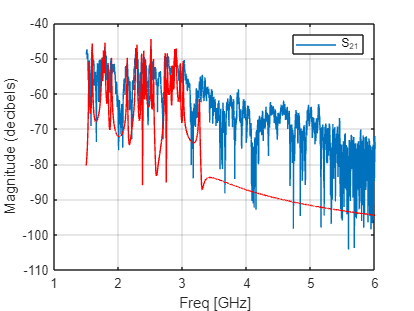

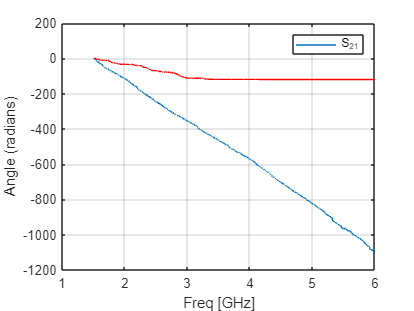

close all; clear;

% look for all the files named "testX.s2p"
% and open them as s-parameter objects in a list
fileprefix = "test";
directory = pwd;

% Get a list of all files in the directory
files = dir(fullfile(directory, [fileprefix + '*.s2p']));
% Determine the number of files found
num_files = numel(files);

% Initialize a cell array to store the data from each file
sparamCell = cell(1, num_files);
figure;
for i = 1:num_files
    % Construct the filename
    filename = fullfile(directory, files(i).name);
    
    params = sparameters(filename);
    sparamCell{i} = params;
    %params = rfparam(dataCell{i}, 2, 1);
    orig_data = sparameters(filename);
    freq = params.Frequencies;
    s21_data = rfparam(sparamCell{i}, 2, 1);
    
    num_points = length(freq)*2;
    fs = 10e9; % sampling frequency
    num_ports = params.NumPorts;

    scale = 1e9; % scale for plotting in smaller numbers

    orig_data = read(rfdata.data,filename);

    fit_data = rationalfit(freq,s21_data);
    % pole-zero, gain
    [num_t, den_t] = bilinear(fit_data.A, fit_data.C,1, fs);

    [resp,freq] = freqresp(fit_data,freq);

    figure
    title('Rational fitting of S21 magnitude')
    plot(orig_data,'S21','dB')
    hold on
    plot(freq/1e9,20*log10(abs(resp)),'r');
    figure
    title('Rational fitting of S21 angle')
    plot(orig_data,'S21','Angle (radians)')
    hold on
    plot(freq/1e9,unwrap(angle(resp)),'r')
    
    % Time vector
    %t_axis = linspace(0, 1/1e6, 505);
    time = (0:num_points-1) / fs;
    time = time.';


    % Frequency response (transformed S-parameters)
    %H = freqz(num_t, den_t, 2*pi*freq, fs);
    
    % Inverse Fourier transform
    %time_domain_response = ifft(H, num_points);
    %time_domain_response = ifft(transformed_s_params, num_points);
    %time_domain_response = ifft(resp, num_points);
    % Plot or analyze the time-domain responses as needed
%     figure
%     data = s21_data;
%     data_flip = flipud(conj(data(2:end)));        
%     data_total = [data_flip; data];  
%     data_ifft = ifft(data_total, num_points, 'symmetric');    
%     ifft_time = (ifftshift(abs(data_ifft)));

    % s21_data original
    %front_pad_s21_data = [zeros(length(freq), 1);s21_data];
%     figure
%     s21_data_flip = flipud(conj(s21_data(2:end)));
%     s21_data_mirrored = [s21_data_flip;s21_data];
%     s21_data_ifft = ifft(s21_data_mirrored, 1024, 'symmetric');
%     ifft_time = (ifftshift(abs(s21_data_ifft)));

    obj = SParameterChannel('FileName',files(i).name,...
    'PortOrder', [1 2],...
    'MaxNumberOfPoles', 48,...
    'ErrorTolerance', -40,...
    'SampleInterval', 6.25e-12,...
    'StopTime', 40e-9,...
    'TxR',50,...
    'TxC',0.1e-12,...
    'TxAmplitude', 1.0,...
    'TxRiseTime', 40e-12,...
    'TxRTFactor', 0.6,...
    'RxR',50,...
    'RxC',0.2e-12,...
    'Signaling','single-ended',...
    'AggressorDefinition','same-load');
    t = obj.t;
    impulse = obj.ImpulseResponse;
    figure;
    plot(t,impulse);

%     plot(ifft_time)
%     title(files(i).name + " Time Response")
%     xlabel("Time (s)")
%     ylabel("Magnitude")
end

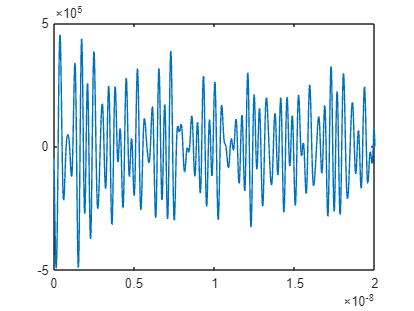

hold off;